clc
clear

train = readtable("results\Performance\training\training_accuracies.csv");
oneMonth = readtable("process_model\generated_data_take_one_month_model\results\training_results.csv");


## Plot results

### Plot colours

% Plot colours
orange = '#FF9A5B';
blue   = '#06ACE9';
purple = '#7E2F8E';
green = '#77AC30';
cyan = '#4DBEEE';
maroon = '#A2142F';
black = '#000000';

### Plot style

% Plot style
line_width = 0.7;

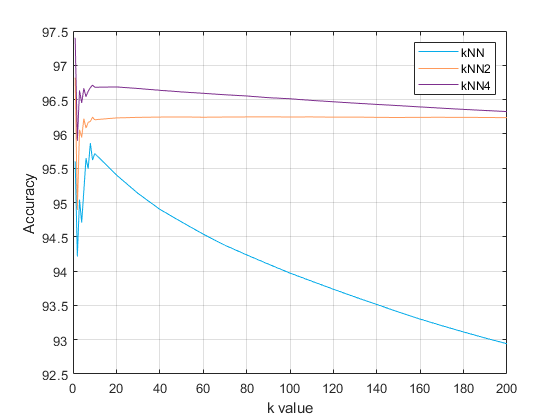

% Plot each model separately 

figure();

plot(train.k, train.kNN, '-', 'LineWidth', line_width, 'Color', blue);
hold on;
plot(train.k, train.kNN2, '-', 'LineWidth', line_width, 'Color', orange);
plot(train.k, train.kNN4, '-', 'LineWidth', line_width, 'Color', purple);
xlabel('k value')
ylabel('Accuracy')
legend('kNN', 'kNN2', 'kNN4');
grid on;
hold off;

% print('results/Performance/testing/useful/SVM_G_Performance', '-dpng', '-r600')


print('results/Performance/training/useful/training_accuracies', '-dpng', '-r600')

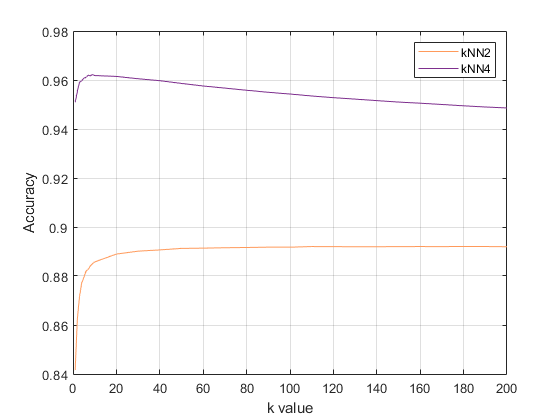

% Plot individual Parameters
figure();

plot(oneMonth.k, oneMonth.kNN2, '-', 'LineWidth', line_width, 'Color', orange);
hold on;
plot(oneMonth.k, oneMonth.kNN4, '-', 'LineWidth', line_width, 'Color', purple);
xlabel('k value')
ylabel('Accuracy')
legend('kNN2', 'kNN4');
grid on;
hold off;

% print('results/Performance/testing/useful/precision_Performance', '-dpng', '-r600')





print('process_model/generated_data_take_one_month_model/results/training_accuracies', '-dpng', '-r600')